%Cargo los archivos
load("CYLINDER_ALL.mat", "VORTALL");
XComplete = VORTALL(:,1:end);
[Uc, Sc, Vc] = svd(XComplete, "econ");

%Time configuration
total = size(XComplete, 2)

total = 151

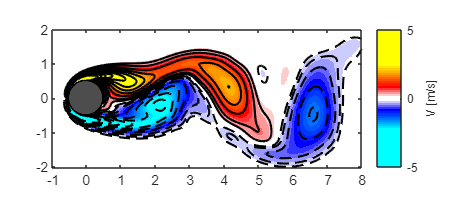

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


tInital = 0;
dt = 0.02*10;
tFinal = total*dt;
time = tInital:dt:tFinal;

%Time configuration for training
tiTrain = 0;
tiIndex = tiTrain/dt + 1;
tfTrain = 24;
tfIndex = tfTrain/dt + 1;
timeTrain = tiTrain:dt:tfTrain;

%Training set
X1 = XComplete(:,tiIndex:tfIndex-1);
X2 = XComplete(:,tiIndex+1:tfIndex);

%Number of modes
r = 7;
[Phi,omega,lambda,b,Xdmd] = DMD(X1,X2,r,time,dt);

%Graph
nx = 199;
ny = 449;
simTime = 15;  %Time
simIndex = simTime/dt; %Index
prueba1 = reshape(Xdmd(:,simIndex),nx,ny);
plotVortex(real(prueba1))


%Ready for forecasting
x0 = X1(:, 1);
b = Phi\x0;
time_dynamics = [];
for i = tfIndex + 1:size(time,2)
    time_dynamics(:,i - tfIndex) = (b.*exp(omega*time(i)));
end
extrapolDMD = Phi*time_dynamics;

%Graph for the forecasting
simTimeForecast = 24.4:dt:30.0;  %Time
simIndexForecast = int32(simTimeForecast./dt); %Index
error = zeros(1, size(simTimeForecast,2));

for i = 1:size(simTimeForecast,2)
    Forecasting01 = reshape(extrapolDMD(:,151-simIndexForecast(i)),nx,ny);
    True01 = reshape(XComplete(:,simIndexForecast(i)),nx,ny);
    error(i) = norm(True01-Forecasting01, "fro");
end


function [Phi ,omega ,lambda ,b,Xdmd] = DMD(X1,X2,r,t,dt)

    [U, S, V] = svd(X1, "econ");

    Ured = U(:, 1:r); 
    Sred = S(1:r, 1:r);
    Vred = V(:, 1:r);

    Atilde = Ured'*X2*Vred*inv(Sred); % low -rank dynamics

    [Wred , D] = eig(Atilde);
    Phi = X2*Vred*inv(Sred)*Wred;

    lambda = diag(D); % discrete -time eigenvalues
    omega = log(lambda)/dt; % continuous -time eigenvalues

    %% Compute DMD mode amplitudes b
    x0 = X1(:, 1); %Condición inicial
    b = Phi\x0;

    %% DMD reconstruction
    mm1 = size(X1, 2); % mm1 = m - 1
    time_dynamics = zeros(r, mm1);


    for iter = 1:mm1 
        time_dynamics(:,iter) = (b.*exp(omega*t(iter)));
    end
    Xdmd = Phi * time_dynamics ;
    
end

function f1 = plotVortex(Vortex)
    
    load CCcool.mat
    f1 = figure;
    vortmin = -5;
    vortmax = 5;

    Vortex(Vortex>vortmax) = vortmax;
    Vortex(Vortex<vortmin) = vortmin;

    imagesc(Vortex);
    colormap(CC);

    xticks([1 50 100 150 200 250 300 350 400 449])
    xticklabels({'-1','0','1','2','3','4','5','6','7','8'})
    yticks([1 50 100 150 199])
    yticklabels({'2','1','0','-1','-2'})
    set(gcf,'Position',[500 300 600 260])
    axis equal
    hold on

    contour(Vortex , [vortmin-0.5:0.5:-0.5 -0.250 -0.125], "--k", "LineWidth",1.4)
    contour(Vortex , [0.250 0.5:0.5:vortmax], "-k", "LineWidth",1.4)
    cb = colorbar;
    ylabel(cb,'V [m/s]');

    theta = [0:0.1:359.9]';
    x = ones(size(theta,2));
    y = ones(size(theta,2));
    x = 49+25*sind(theta);  %Son esos centro porque la imagen está escalada
    y = 99+25*cosd(theta);
    fill(x,y,[.3 .3 .3])  % place cylinder
    plot(x,y,'k','LineWidth',1.2) % cylinder boundary
    hold off

end